# Plot pickup density series at different regions

import NYCTaxi.* 
Demand=DemandClass( 'D:\OneDrive - Columbia University\2017Spring\Research\Data\Data\Demand.mat');

## Specify Query Region and time intervals

Define the region that encloses Time Square 

S_Time_Square=[40.761717, -73.986596;
               40.759927, -73.976280;
               40.755649, -73.985992;
               40.756536, -73.993982;
               40.761530, -73.990447];

% Define another less busy region: China Town
S_China_Town=[40.719869, -74.001430;
              40.717720, -73.995163;
              40.713672, -73.998415;
              40.716242, -74.004374];
% Specify the time interval
interval={'2016-04-30 00:00:00','2016-05-03 23:59:59',hours(1)};

## Calculate pikcup/dropoff density

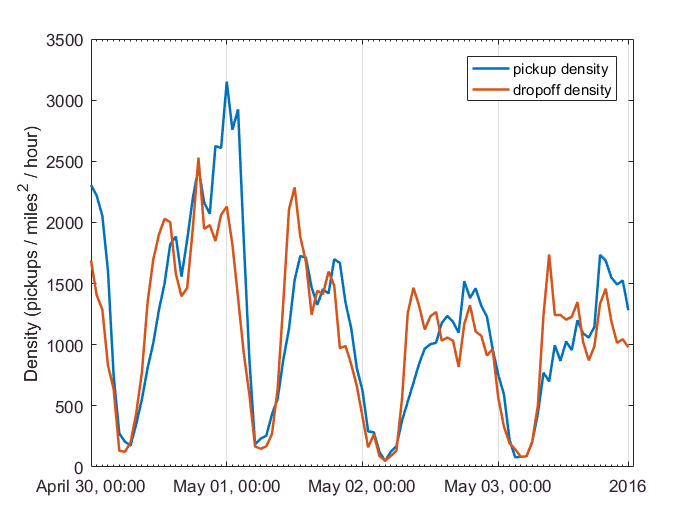

%at Times Square
density_Time_Square=Demand.DemandQuery(interval,S_Time_Square);
%at China Town
[density_China_Town,time]=Demand.DemandQuery(interval,S_China_Town);
% You can use the following to visualize the query results simultaneously
Demand.DemandQuery(interval,S_China_Town,'Type','timeseries');

## Plot Results

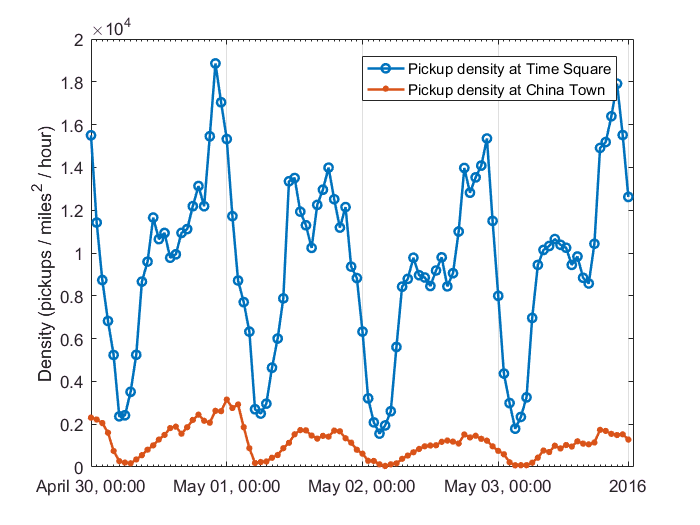

plot(time,[density_Time_Square(1,:)',density_China_Town(1,:)'],...
    'DatetimeTickFormat','MMMM dd, HH:mm')
legend('Pickup density at Time Square','Pickup density at China Town');
ylabel('Density (pickups / miles^2 / hour)')
ax=gca;
set(ax.Children,{'LineWidth','Marker','MarkerSize'},{1.5,'.',13;1.5,'o',5});
ax.XTick=min(time):days(1):max(time);
ax.XLim.Format='u-M-dd HH:mm';
ax.XAxis.MinorTick='on';
ax.XAxis.MinorTickValues=time;
ax.XGrid='on';
ax.XTickLabel{5}='2016';
ax.XTick(5)=max(time);

## Plot with Confidence intervals

clearvars  -except Demand

## Collect Data

interval={char(min(Demand.Demand.time)),char(max(Demand.Demand.time)),hours(1)};
[data,time]=Demand.DemandQuery(interval);
time=time(:);
data=shiftdim(data,1);%shift the time dimension to the 4th dimension
n=length(time);
density_Time_Square = zeros( n,1); density_China_Town = zeros( n,1);
for i=1:n
    density_Time_Square(i)=ltln2val( data(:,:,1,i), Demand.R, 40.758854, -73.985061, 'nearest');
    density_China_Town(i)=ltln2val( data(:,:,1,i), Demand.R, 40.714374, -73.996194, 'nearest');
end
tb=table(time,density_Time_Square,density_China_Town);
tb.isweekend=isweekend(tb.time);
tb.hours=hour(tb.time);
results=grpstats(tb,{'isweekend','hours'},...
    {'mean',@median,'meanci', @(x)quantile(x,0.25),@(x)quantile(x,0.75)},...
    'DataVars',{'density_Time_Square','density_China_Town'});
results.Properties.VariableNames= replace( results.Properties.VariableNames,...
    {'Fun4','Fun5'},{'lower_quartile','upper_quartile'});

## Plot confidence intervals

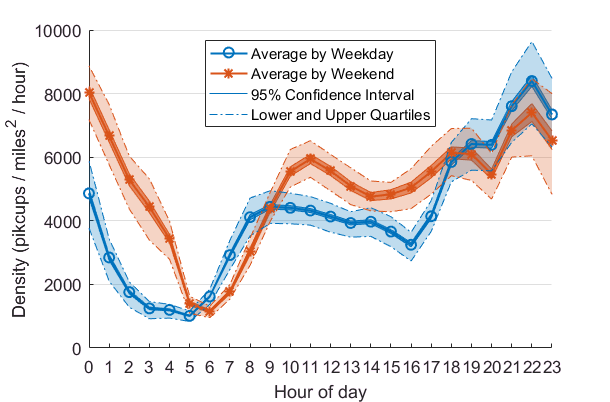

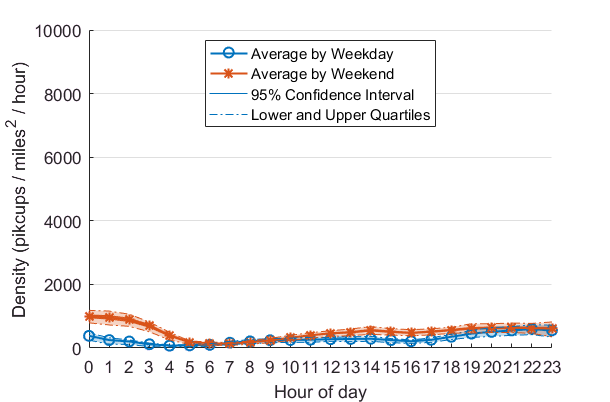

import NYCTaxi.boundedline
import NYCTaxi.outlinebounds

varnames={'mean_density_Time_Square','mean_density_China_Town'};
labelnames={'Density (pikcups / miles^2 / hour)' ,  'Density (pikcups / miles^2 / hour)'};
tb=results;

for i=1:2   
    f(i)=figure('PaperType','usletter','Position',[138.6000 394.6000 488 321.6000]);
    X=reshape(tb.hours,[],2) ; Y=reshape(  tb.(varnames{i}),[],2);
    lowerror=tb.(varnames{i}) - tb.( regexprep(varnames{i},'^\w+?_','lower_quartile_'));
    uperror= tb.( regexprep(varnames{i},'^\w+?_','upper_quartile_'))-tb.(varnames{i});
    outer_bd=cat(2, reshape( lowerror,[],1,2),...
                    reshape( uperror ,[],1,2));
    lowerror= tb.(varnames{i}) - tb.( regexprep(varnames{i},'^\w+?_','meanci_'))(:,1);
    uperror= tb.( regexprep(varnames{i},'^\w+?_','meanci_'))(:,2)-tb.(varnames{i});
    inner_bd=cat(2, reshape( lowerror,[],1,2),...
                    reshape( uperror ,[],1,2));
    [h,p]=boundedline(     X , Y ,  inner_bd ,'alpha','transparency', 0.6);
    h_bd1=outlinebounds(h, p); set(h_bd1,{'LineWidth'},{0.5;0.5});
    [h,p]=boundedline(     X , Y ,  outer_bd ,'alpha','transparency', 0.25);
    h_bd2=outlinebounds(h, p); set(h_bd2,{'LineWidth','LineStyle'},{0.1,'-.';0.1,'-.'});
    legend([h;h_bd1(1);h_bd2(1)],'Average by Weekday','Average by Weekend', ...
          '95% Confidence Interval',...
          'Lower and Upper Quartiles',...
        'Location','best');
    
    set(h,{'Marker','LineStyle','LineWidth'},{ 'o','-',1.2;  '*','-',1.2});
    h=gca;h.XTick=0:23;h.YGrid='on';xlim([0,23])
    ylabel(labelnames{i});xlabel('Hour of day');
end
f(2).Children(2).YLim=f(1).Children(2).YLim;
if exist('figures','dir')~=7, mkdir('figures'),end
savefig(f,'./figures/Density_at_Times_Square_Vs_China_Town.fig ','compact');

## Density Matrix Plot

% init
clear;close all;clc;
import NYCTaxi.*
Demand=DemandClass('D:\OneDrive - Columbia University\2017Spring\Research\Data\Data\Demand.mat');

calculate density at Times Square and China Town

S_Time_Square=[40.760325, -73.987427;
               40.758015, -73.981804;
               40.756802, -73.982674;
               40.759193, -73.988442];
S_China_Town=[ 40.717751, -74.000271;
               40.716225, -73.995899;
               40.713919, -73.997749;
               40.715119, -74.002132];
interval={'2016-05-01 00:00:00','2016-05-07 23:59:59',...
            hours(1)};

Plot Density Matrix

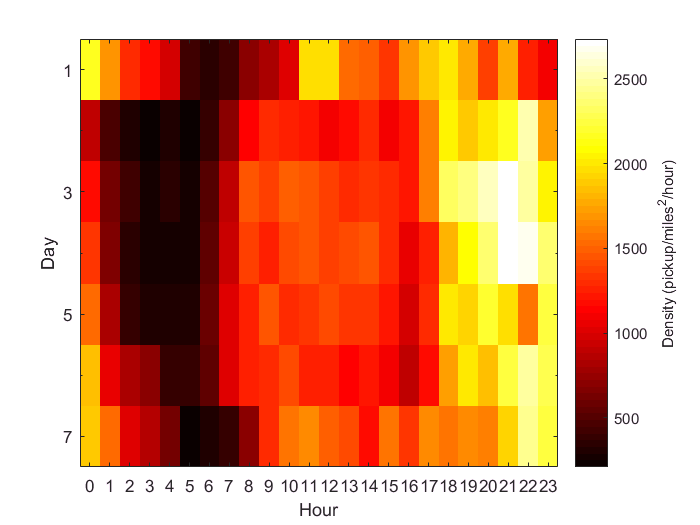

[demand_TS,~,area_TS,h(1) ]=Demand.DemandQuery(interval,S_Time_Square,'Type','DensityMatrix');

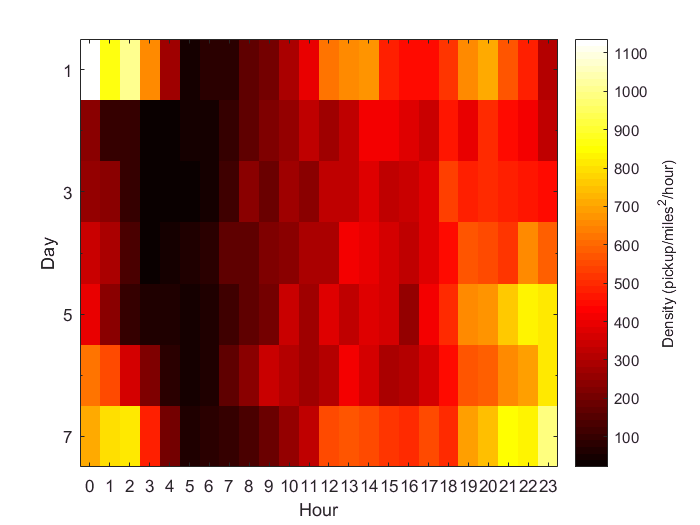

f(1)=gcf;
figure
[demand_CT,time,area_CT,h(2) ]=Demand.DemandQuery(interval,S_China_Town,'Type','DensityMatrix');

f(2)=gcf;